clc
clear

wto=120000 %kg

wto = 120000

range=4500 %km

range = 4500

passenger_num=150

passenger_num = 150

%ltd=   %lift to drag ratio

%weight ratio intuition
w1_to=0.99  %start and warm up

w1_to = 0.9900

w2_1=0.99   %taxi

w2_1 = 0.9900

w3_2=0.995  %take-off

w3_2 = 0.9950

w4_3=0.985   %climb

w4_3 = 0.9850

w6_5=0.99   %descent

w6_5 = 0.9900

w8_7=0.985   %climb

w8_7 = 0.9850

w10_9=0.99   %descent

w10_9 = 0.9900

w11_10=0.992   %landing taxi shut down

w11_10 = 0.9920


%calculated weight ratio
c=0.7   %thrust-specific fuel consumption 

c = 0.7000

v=462   %miles/hr cruise velocity

v = 462

l2d=15   %L/D at cruise

l2d = 15

R1=1400   %miles distance from taiwan to palau

R1 = 1400

R2=v/6   %wiles distance of loitering at palau for 20 min

R2 = 77


w5_4=1/exp(R1*(c/v)/l2d)   %cruise from taiwan to palau

w5_4 = 0.8681

w7_6=1/exp(R2*(c/v)/l2d)   %loiter at palau for 10 min to release paratroopers

w7_6 = 0.9923

w9_8=1/exp(R1*(c/v)/l2d)   %cruise from palau to taiwan

w9_8 = 0.8681


mff1=w1_to*w2_1*w3_2*w4_3*w5_4*w6_5   %before release paratroopers

mff1 = 0.8256

mff2=w7_6*w8_7*w9_8*w10_9*w11_10   %after release paratroopers

mff2 = 0.8333



wcrew=4*80

wcrew = 320

wpl=passenger_num*120

wpl = 18000


w7=(wto*mff1)-wpl   %weight of aircraft after release paratroopers

w7 = 8.1067e+04

wfused=(1-mff1)*wto+(1-mff2)*w7

wfused = 3.4448e+04


wtfo=0

wtfo = 0

we=wto-wfused-wcrew-wpl-wtfo

we = 6.7232e+04


x=[265352;141000;195000;70307;402000;265352;141400;145000;wto]

x =       265352
      141000
      195000
       70307
      402000
      265352
      141400
      145000
      120000


y=[128140;76500;60000;34382;181000;128140;60800;66230;we]

y = 	1.0e+05 *

    1.2814
    0.7650
    0.6000
    0.3438
    1.8100
    1.2814
    0.6080
    0.6623
    0.6723


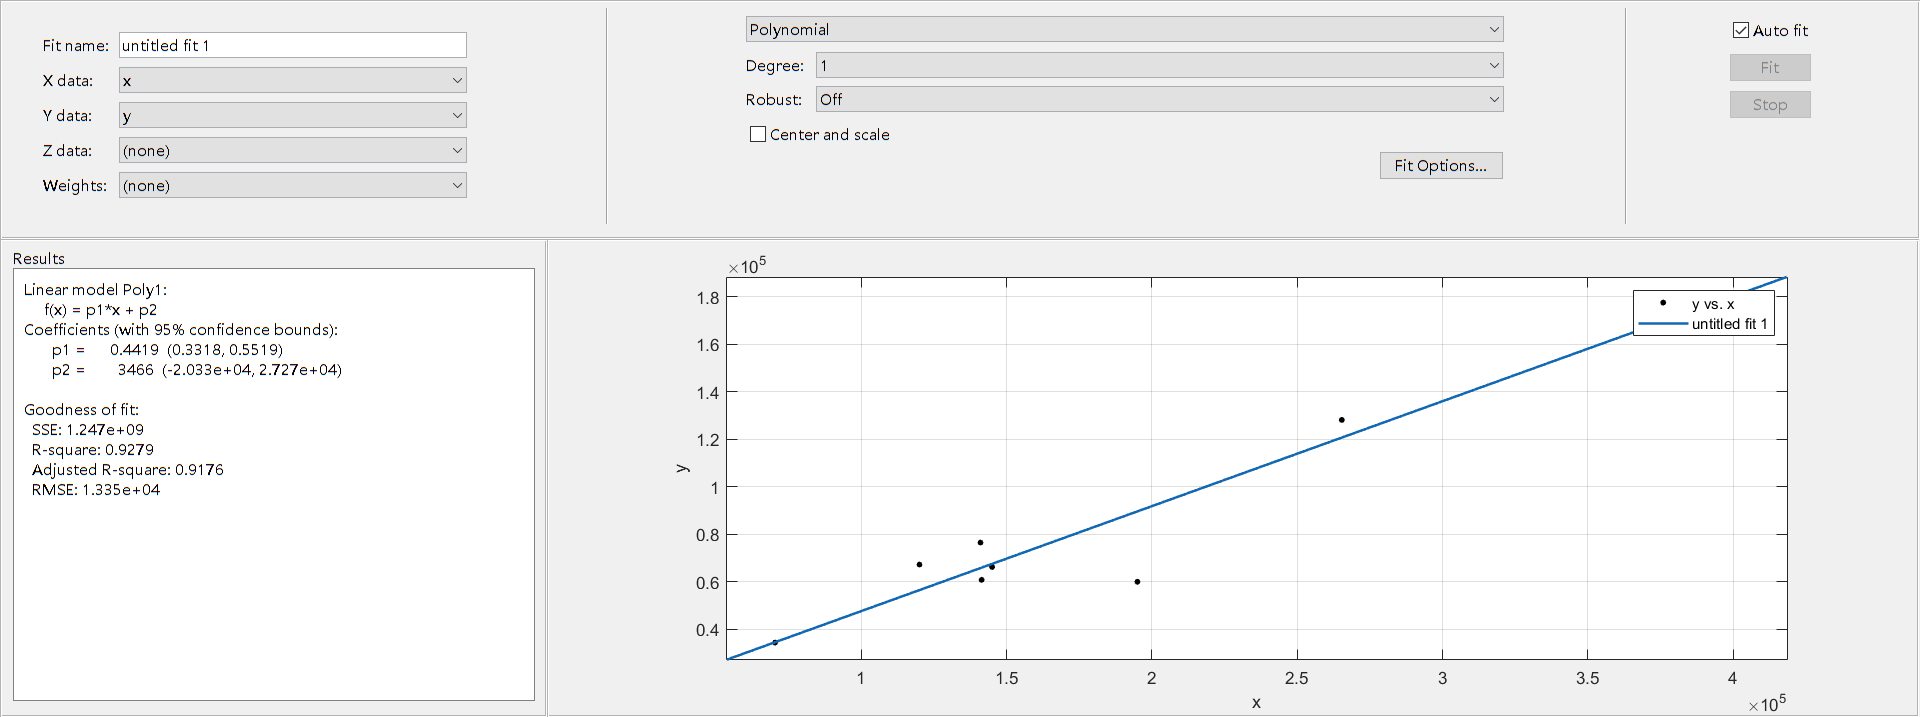


cftool(x,y)